# Battery Charging Model

This live script models the charging behavior of a lithium-ion battery using an RC (resistor-capacitor) circuit approximation. The parameters are based on the Panasonic NCA103450 cell. The script calculates voltage, current, and power over time, and visualizes each with a plot.

## Clear Workspace

clear , clc, close all;

##  Define Constants 

These values are estimated to give a realistic time constant for charging. You can modify R and C to simulate different battery conditions.

V_max = 4.2;      % Maximum charging voltage (Volts)
R = 0.25;         % Equivalent resistance (Ohms)
C = 11520;        % Equivalent capacitance (Farads)

## Set up Time Vector 

Time resolution can be adjusted to smooth curves in the plots 

tau = R * C;            % Time constant (tau) 
t_end = 5 * tau;        % Total simulation time (~99% charge)
t = 0:0.01:t_end;       % Time vector with 0.01-second intervals

## Calculate Voltage over Time

Voltage is computed using the exponential charging equation

V_t = ComputeVoltage(V_max, tau, t);   

## Calculate Current over Time

 Current is calculated as an exponential decay function

I_t = ComputeCurrent(V_max, R, tau, t);    

## Calculate Instantaneous Power over Time

 Power is calculated as the pointwise product of voltage and current

P_t = ComputePower(V_t, I_t)

P_t =          0    0.0002    0.0005    0.0007    0.0010    0.0012    0.0015    0.0017    0.0020    0.0022    0.0024    0.0027    0.0029    0.0032    0.0034    0.0037    0.0039    0.0042    0.0044    0.0047    0.0049    0.0051    0.0054    0.0056    0.0059    0.0061    0.0064    0.0066    0.0069    0.0071    0.0073    0.0076    0.0078    0.0081    0.0083    0.0086    0.0088    0.0091    0.0093    0.0096    0.0098    0.0100    0.0103    0.0105    0.0108    0.0110    0.0113    0.0115    0.0118    0.0120


## Graph Voltage vs. Time

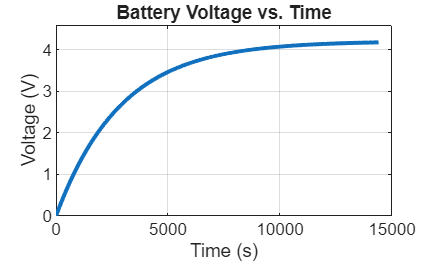

PlotVoltage(t, V_t);

## Graph Current vs. Time

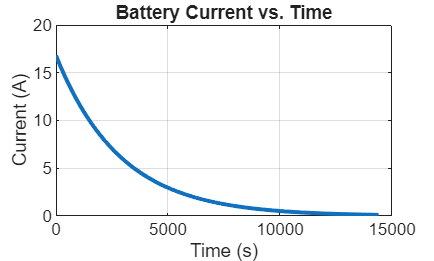

PlotCurrent(t, I_t);

## Graph Power vs. Time

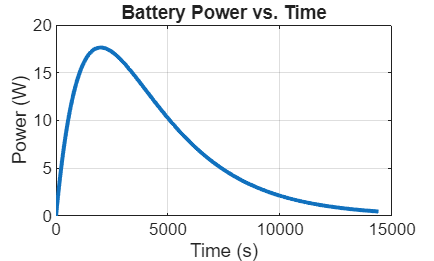

PlotPower(t, P_t);